clear all

f1d=@(x)x.^2

f1d = function_handle with value:
    @(x)x.^2


xi=linspace(0,1,50);
fi=f1d(xi);
Int=MyTrapz(fi,xi)

Int = 0.3334

Define and plot function to see how it looks like

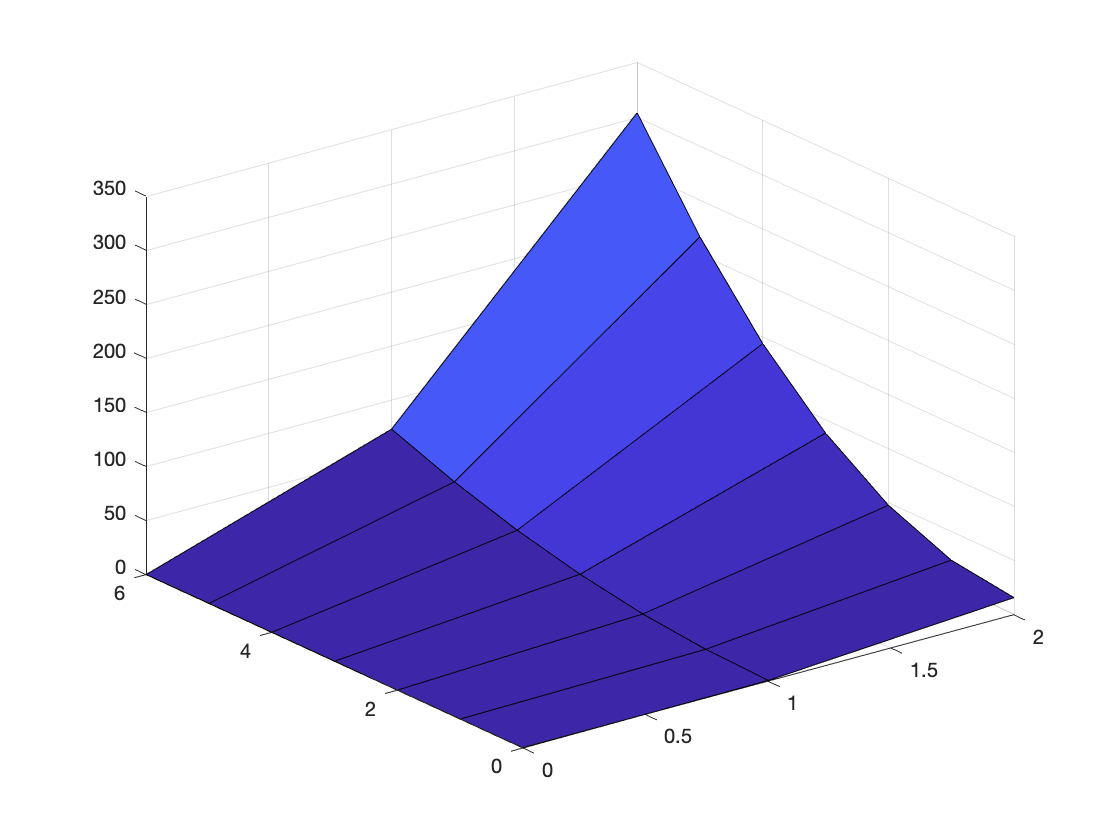

f=@(x,y) x.^4+2.*y.^2.*x.^2;
xi=linspace(0,2,3);

yi=linspace(0,6,7);

Deltax=xi(2)-xi(1);
Deltay=yi(2)-yi(1);


[Xi,Yi]=meshgrid(xi,yi);
Fi=f(Xi,Yi);
surf(Xi,Yi,Fi);

tempfunc=zeros(size(yi));
g=@(y) (32/5)+16*y.^2/3;

for j=1:length(yi)
    tempfunc(j)=MyTrapz(Fi(j,:),xi);
end

% Can also use MATLAB trapz() function to integrate
tempMATLAB=Deltax*trapz(Fi,2)

tempMATLAB =      9
    15
    33
    63
   105
   159
   225


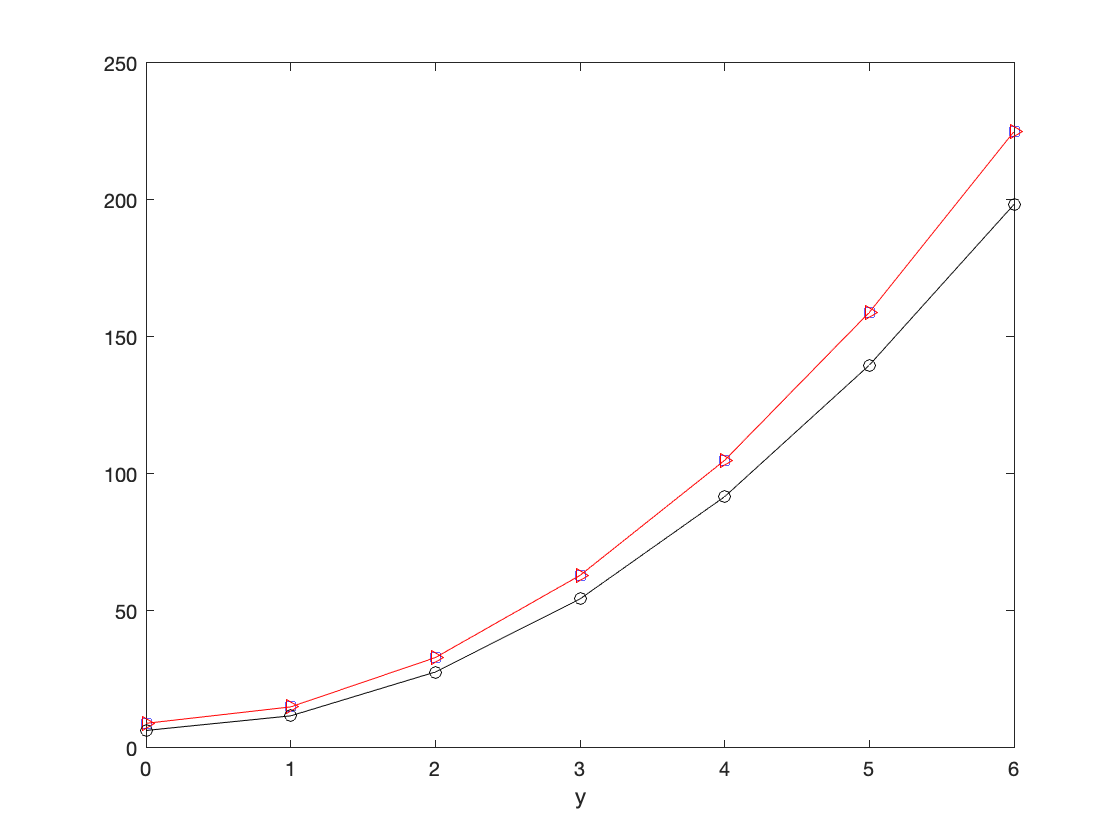


plot(yi,tempfunc,'bs-',yi,tempMATLAB,'r>-',yi,g(yi),'ko-')
xlabel('y')



MyTrapz(tempfunc,yi)

ans = 492

Int=MyTrapz2D(Fi,xi,yi)

Int = 492

Use trapz() function in MATLAB


temp=trapz(Deltay,Fi,1)

temp =      0   152   680


trapz(Deltax,temp)

ans = 492


trapz(trapz(Fi))*Deltax*Deltay

ans = 492

function Int=MyTrapz2D(Fi,xi,yi)
    Deltax=xi(2)-xi(1);
    Deltay=yi(2)-yi(1);
    
    Intx=zeros(1,length(yi));
    
%Integrate in the x direction  
    Intx(:)=Fi(:,1);
    Intx(:)=Intx(:)+2*sum(Fi(:,2:end-1),2);
    Intx(:)=Intx(:)+Fi(:,end);
    Intx(:)=(Deltax/2.0)*Intx(:);
    
%Then Integral in the y direction    
    Int=Intx(1);
    Int=Int+2*sum(Intx(2:end-1));
    Int=Int+Intx(end);
    Int=(Deltay/2.0)*Int;
    
end

function Int=MyTrapz(Fi,xi)
    Deltax=xi(2)-xi(1);
    
    Int=0;
    
%Integrate in the x direction  
    Int=Fi(1);
    Int=Int+2*sum(Fi(2:end-1));
    Int=Int+Fi(end);
    Int=(Deltax/2.0)*Int;    
end

%------------------------------